การคำนวณหาค่า Q ที่สถานี S3 (M7) โดยใช้ค่า Q ที่สถานี S1 และ S2 ระหว่าง Day 1 และ Day 60 

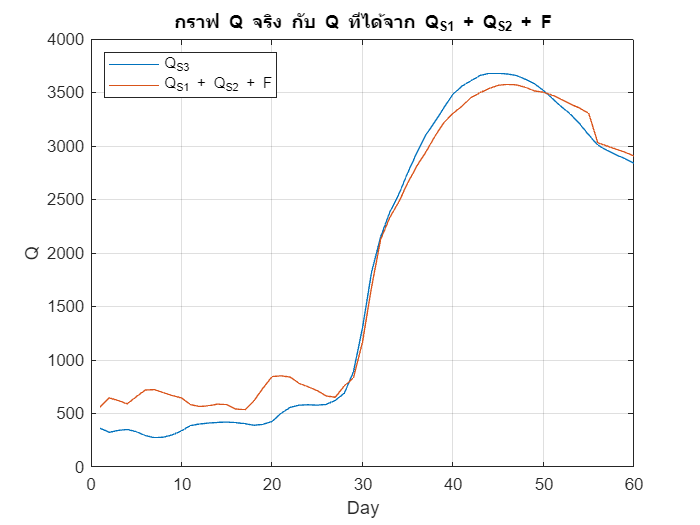

mdl = fittype('x+a*x','coefficients',{'a'},'independent','x','dependent','y');
fitResult = fit(Q1+Q2,Q3,mdl,'StartPoint',0);
coeffs = coeffvalues(fitResult);
a = coeffs(1);
nv = (Q1+Q2) + a * (Q1+Q2);
plot(Q3)
hold on
plot(nv)
hold off
grid on
xlabel('Day');
ylabel('Q');
title('กราฟ Q จริง กับ Q ที่ได้จาก Q_S1 + Q_S2 + F');
legend({'Q_S3','Q_S1 + Q_S2 + F'},'Location','northwest');

Performance ของการ Fitting

R_squared = 1 - sum((Q3 - nv).^2) / sum((Q3 - mean(Q3)).^2);
MAE = sum(abs(Q3 - nv))/length(Q3);
MSE = (sum((Q3 - nv).^2))/(length(Q3));
fprintf('R_squared = %f\nMAE = %f\nMSE = %f', R_squared,MAE,MSE);

R_squared = 0.979510
MAE = 165.735615
MSE = 39983.760966

การแสดงผลของค่า factor ที่เกิดขึ้น เมื่อเปรียบเทียบกับข้อมูล Q จริง

fprintf('Q3 = Q1 + Q2 + F*(Q1+Q2)\nF = %f\nF*(Q1+Q2) จะเป็นปริมาณ Q ที่เพิ่มขึ้นมาระหว่างทางไป S3 โดยที่ปริมาณของ Q ที่เพิ่มขึ้นจะขึ้นอยู่กับปริมาณของ Q1+Q2',a);

Q3 = Q1 + Q2 + F*(Q1+Q2)
F = 0.330467
F*(Q1+Q2) จะเป็นปริมาณ Q ที่เพิ่มขึ้นมาระหว่างทางไป S3 โดยที่ปริมาณของ Q ที่เพิ่มขึ้นจะขึ้นอยู่กับปริมาณของ Q1+Q2